# The Advection Equation

The advection equation 


$$\frac{\partial C}{\partial t} + v\frac{\partial C}{\partial x} =0$$


represent the movement of, for example, the concentration $C$ of a substance with a velocity $v$ along the x axis. There are several numerical techniques for solving this equation, but not all of them give good results! In what follows we will numerically integrate these equations using a Gaussian profile as an initial condition. The equation preserves the shape of this profile and so the final solution from the nuerical algorithm should look exactly the same as the initial one. 

## The Upwind Scheme

The upwind scheme is one of the simplest, but it suffers from a numerical diffusion. 

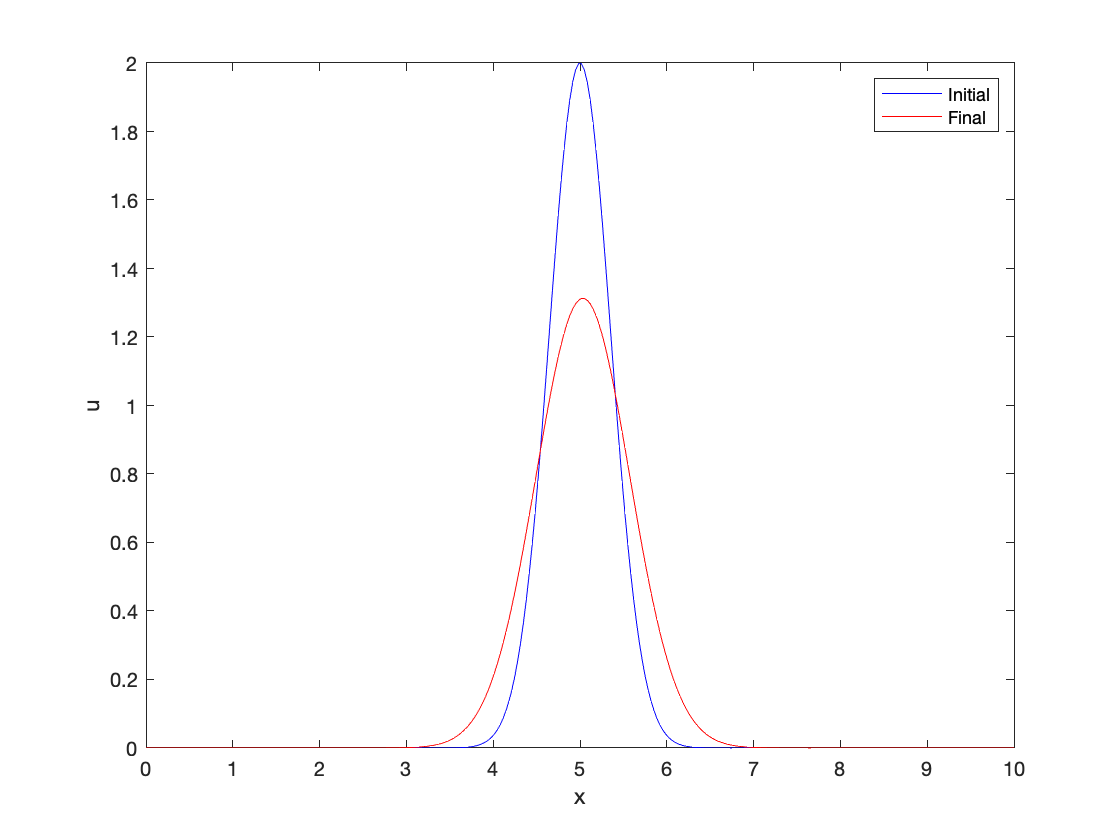

v = 1.0;      % The velocity (assumed to be positive)

% Define the grid
courant_num = 0.5;  % The desired Courant number

x_min   = 0.0;   % Lower boundary of the grid
x_max   = 10.0;  % Upper grid boundary
n_space = 300.0; % Number of grid points in the spatial direction
t_min   = 0.0;   % Initial time
t_max   = 10.0;  % Final time

x  = linspace(x_min, x_max, n_space);
dx = x(2) - x(1);

dt = courant_num * dx / v;
t  = t_min : dt : t_max;

n_x = length(x);
n_t = length(t);

% Pre-allocate storage: 
u_solution = zeros(n_t, n_x);

% Set up initial condition. We will take this to be a Gaussian
my_gauss = @(x, a, m, s) a * exp(-((x-m)/s).^2);

gauss_amplitude = 2.0;
gauss_mean      = mean(x);
gauss_var       = 0.5;

u_solution(1,:) = my_gauss(x, gauss_amplitude, gauss_mean, gauss_var);

% Solve the equation
for i_step = 2 : n_t
    
    u_solution(i_step,:) = UpWindStepMMEES(u_solution(i_step-1,:), courant_num);
    
end

figure
plot(x, u_solution(1,:), 'b', x, u_solution(end,:), 'r')
legend('Initial', 'Final')
xlabel('x')
ylabel('u')


upwind_soluion = u_solution;

We can see from the figure that the final curve does not have the same height as the original (whereas it should), and what is more, it has a greate spread indicating that there has been a numerical diffusion. 

## The FTCS Scheme

THe Forward-Time-Centered-Space scheme can be used to solve certain types of partial differential equations, but not the advection equation. This is because this scheme is unconditionally unstable when applied to this type of equation. In the example below we start with the same initial conditions as above. 

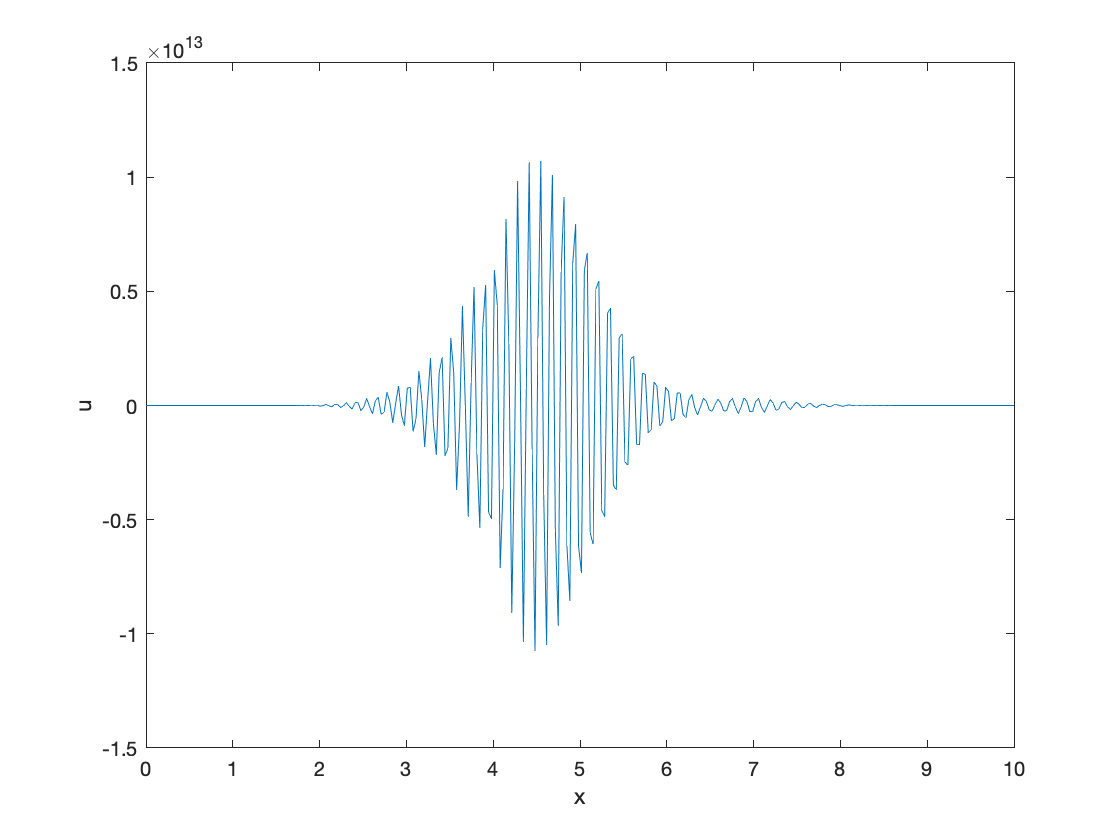

u_solution      = zeros(n_t, n_x);
u_solution(1,:) = my_gauss(x, gauss_amplitude, gauss_mean, gauss_var);

for i_step = 2 : n_t
    
    u_solution(i_step,:) = FTCSStepMMEES(u_solution(i_step-1,:), courant_num);
    
end

figure
plot(x, u_solution(end,:))
xlabel('x')
ylabel('u')


ftcs_solution = u_solution;

If we look at the scaling on the y-axis we immediately see that the numbers depicted in this graph are huge! This shows the instability in this method for this type of equation. 

## The Lax-Friedrichs Scheme

The Lax-Friedrichs scheme is another popular method, but it too suffers from numerical diffusion. 

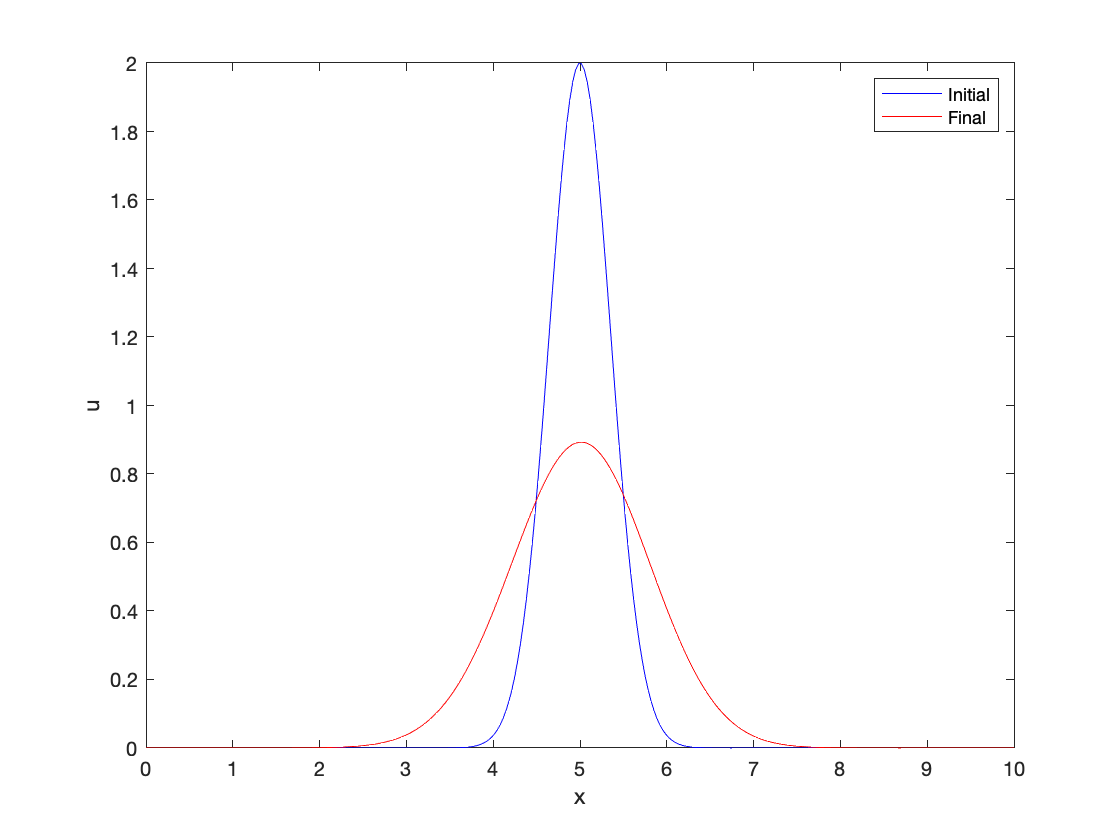

u_solution      = zeros(n_t, n_x);
u_solution(1,:) = my_gauss(x, gauss_amplitude, gauss_mean, gauss_var);

for i_step = 2 : n_t
    
    u_solution(i_step,:) = LaxFriedrichsStepMMEES(u_solution(i_step-1,:), courant_num);
    
end

figure
plot(x, u_solution(1,:), 'b', x, u_solution(end,:), 'r')
legend('Initial', 'Final')
xlabel('x')
ylabel('u')


laxf_solution = u_solution;

## The Lax-Wendroff Scheme

The Lax-Wendroff scheme however performs quite well and is quite robust. 

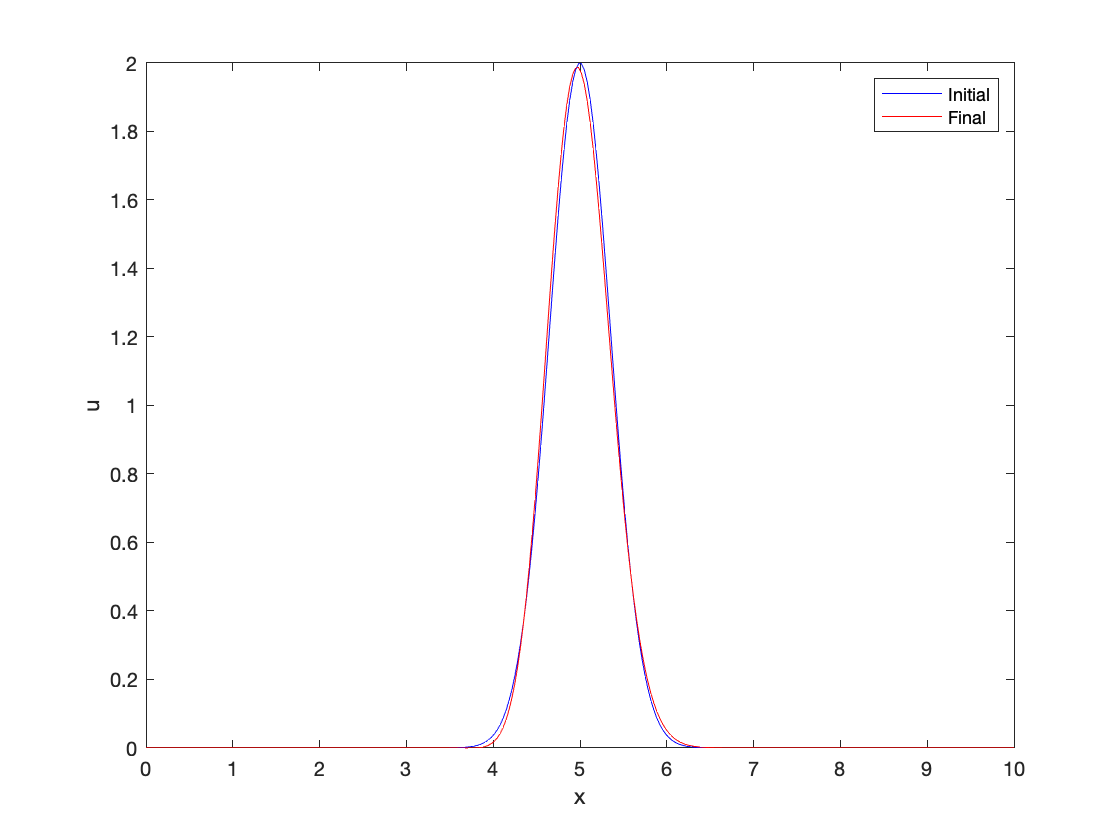

u_solution      = zeros(n_t, n_x);
u_solution(1,:) = my_gauss(x, gauss_amplitude, gauss_mean, gauss_var);

for i_step = 2 : n_t
    
    u_solution(i_step,:) = LaxWendroffStepMMEES(u_solution(i_step-1,:), courant_num);
    
end

figure
plot(x, u_solution(1,:), 'b', x, u_solution(end,:), 'r')
legend('Initial', 'Final')
xlabel('x')
ylabel('u')

laxw_solution = u_solution;

We can see from the figure that the final solution matches the initial solution very well. There is a small discrepency in the wings of the profile, but on the whole this method works quite well. 

***Exercise:**** Repeat these calculations using larger number of grid points and smaller number of grid points and compare your results between the different  algorithms and with the plots shows here. How does the accuracy of the solutions change? Can you find a number of steps that makes the FTCS scheme work?*